# The Gauntlet Challenge

**Authors: Dexter Friis-Hecht, Dokyun Kim, Ellen Sun**

Using the data from the Neato's LiDAR sensor, create a map of the gauntlet. Then, program it to safely navigate itself to the 'Barrel of Benevolnce' while avoiding all obstacles. 

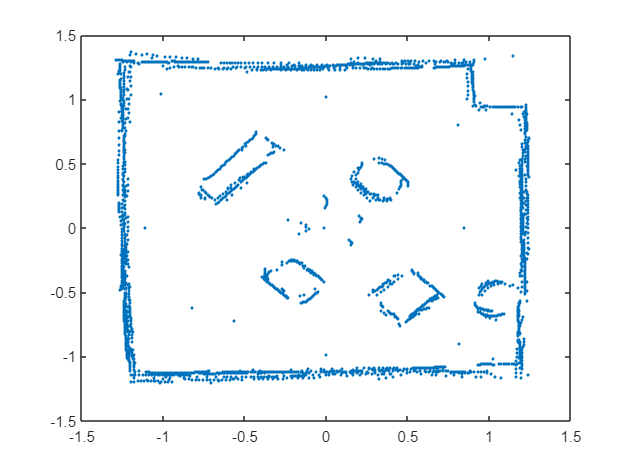

warning('off')
close all, clear all, clc

% Load LiDAR data
load('map.mat')
data_cart = all_points';
% Convert cartesian to polar
[t,rho] = cart2pol(data_cart(:,1),data_cart(:,2));
data = [rho rad2deg(t)];
% Display the scanned map of Gauntlet
figure()
plot(data_cart(:,1),data_cart(:,2),".")
hold on;

## Using Random sample consensus (RANSAC) to identify lines

!!! Re-run previous section before re-running this section !!!

In order to identify the walls and obstacles, we need to find lines in the laser scans using a line-fitting technique. 

There are methods like linear regression and principal component analysis, but these methods are highly vulnerable to outliers.

The RANSAC algorithm is often used for identifying lines in LiDAR scans since it is robust in the presence of outliers.

RANSAC follows the steps described below:

- Select two random points from the dataset to define a line.

- Split the remaining points into two groups: Inliers & Outliers

- Repeat the 2 steps above $n$ times

- Keep the line with most inliers

The code below will find 35 lines in the dataset using the `find_RANSAC` function.

First parameter is the dataset used, second parameter is the inlier threshold, and the third parameter is the number of random selection. 

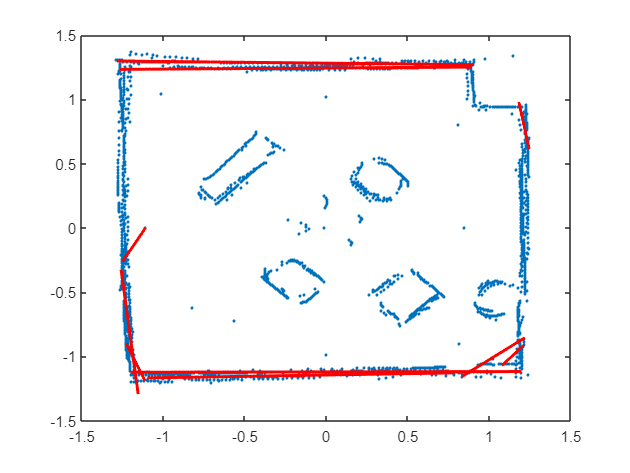

% Run RANSAC
iter = 10;

% Initialize array
m_array = ones(iter,1);
b_array = ones(iter,1);
ep1s = ones(iter,1);
ep2s =ones(iter,1);


for i = 1:iter
    % Do RANSAC 'iter' times
    [m_b,ends,inlier,outlier,bestfit_point,polar]=find_RANSAC(data,0.015,1000);
    m_array(i) = m_b(1);
    b_array(i) = m_b(2);
    ep1s(i)=ends(1,1);
    ep2s(i)=ends(2,1);

    % Plot line
    x = linspace(ends(1,1),ends(2,1));
    y = m_b(1)*x+m_b(2);
    plot(x,y,'r',LineWidth=2)

    % Remove inliers, repeat RANSAC with new data
    [t,rho]=cart2pol(outlier(:,1),outlier(:,2));
    data = [rho rad2deg(t)];
end
hold off;

## Potential Fields

To make the Neato avoid obstacles while pathing towards the barrel, we can give the lines defining the object negative potential while giving the barrel a potisive potential. In a 3D space, the obstacles will appear as deep troughs while the barrel will appear as a deep valley. 

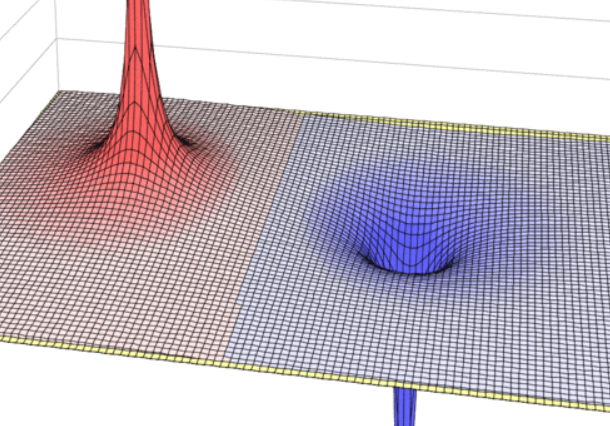

The gauntlet will have multiple of the red peaks and exactly one blue valley. Using the gradient descent algorithm used in `Flatlands`, we can guide the Neato towards the barrel while avoiding the obstacles.

To give a line $y =  mx+b$ negative potential, we need to sum up all the potential created by the points on the line. 

The potential field due to a point (a,b) is defined by


$$V(x,y) = k*log\sqrt{(x-a)^2+(y-b)^2}$$


where $k=1$ gives a negative potential, and $k=-1 $ gives a positive potential.

To evaluate this function for every point along a line, we need to use a line integral.

The line integral of a function$f$ along a curve $C$ is expressed as


$$\int_C f dl$$


The most robust way to evaluate this is parametrizing C with $x(t)$ and $y(t)$. Think about $x(t)$ and $y(t)$ as the position of a particle that is moving along the curve from t = a to t = b. Then, the differential $dl$ is the **distance** the particle moves along the curve during a small timestep $dt$.


$$dl = \sqrt{(\frac{dx}{dt})^2+(\frac{dy}{dt})^2} dt$$


Then, the line integral can be reduced to be in terms of time.


$$\int_c fdl = \int_Cf((x(t),y(t))\sqrt{(\frac{dx}{dt})^2+(\frac{dy}{dt})^2} dt$$


The steps to evaluate the potential field function along a line $y = mx+b$ with endpoints $(x_1,y_1),(x_2,y_2)$ is shown below.

- Parametrize the line segment into $a(t) = t$ and $b(t) = mt+b$, $x_1 \leq t \leq x_2$

- We then get $\frac{da}{dt} = 1$ and  $\frac{db}{dt} = m$

- Substitute into line integral: $V_C(x,y) = \int_{x_1}^{x_2}log\sqrt{(x-t)^2+(y-(mt+b))^2}*\sqrt{1-m^2} dt$

The code below will calculate the potential fields of all the lines found by RANSAC in the previous section using the `line_potential` function.

pots = [];


pots =

     []



for i = 1:iter
% Potential field for lines identified by RANSAC
    m = m_array(i);
    b = b_array(i);
    ep1 = ep1s(i);
    ep2 = ep2s(i);
    [potential,Xp,Yp]=line_potential(m,b,ep1,ep2);
    
    if i == 1
        X = Xp;
        Y = Yp;
        pots = potential;
    else
        pots = pots + potential;
    end
end

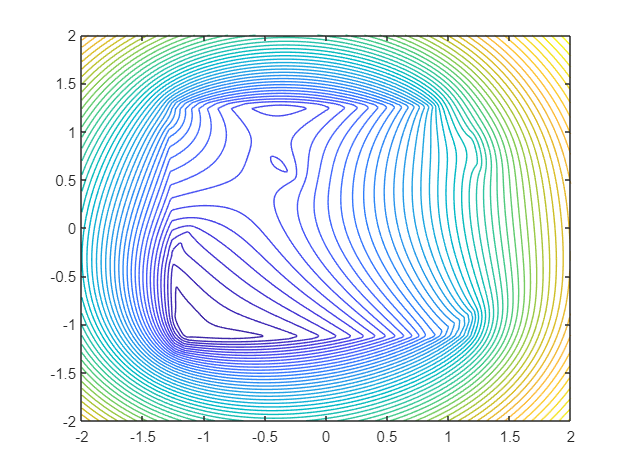

contour(X,Y,pots,50)

## Account for Error

%pot for missing line
x1=-0.455;
y1=0.747;
x2=-0.263;
y2=0.515;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,~,~] = line_potential(new_m,new_b,x1,x2);
pots = pots + pot;

%pot for other missing line
x1=-0.173412;
y1=-0.36;
x2=-0.305;
y2=-0.533;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,~,~] = line_potential(new_m,new_b,x1,x2);
pots_test = pots_test + pot;

%pot for top wall line
x1=-1.2625;
y1=1.075;
x2=1.15;
y2=1.1;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,~,~] = line_potential(new_m,new_b,x1,x2);
pots = pots + pot;

Unrecognized function or variable 'pots_test'.

%pot for left wall line
x1=-1.2875;
y1=1.05;
x2=-1.2375;
y2=-1.3;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,~,~] = line_potential(new_m,new_b,x1,x2);
pots = pots + pot;

%pot for right wall line
x1=1.225;
y1=1.0875;
x2=1.275;
y2=-1.275;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,~,~] = line_potential(new_m,new_b,x1,x2);
pots_test = pots_test + pot;

## Barrel of Benevolence

% Adds a circle to where BoB should be
[pot_circ,x,y] = circ_potential(-1.1,0.5,0.14);
pots_test = pots_test+pot_circ;

point_pot = []
for i = 1:length(X)
    x = X(1,i);
    for j = 1:length(Y)
        y = Y(j, 1);
        point_pot(j,i) = -700 * (log(sqrt((x-0.8375).^2+(y-.5).^2)) + log(sqrt((x-0.4625).^2+(y-.05).^2)) + log(sqrt((x-0.65).^2+(y-.2375).^2)) + log(sqrt((x-0.05).^2+(y+.5).^2)) + log(sqrt((x-.2875).^2+(y+.35).^2)));
    end
end

pots_pt = pots_test + point_pot;


figure()
hold on;
contour(X,Y,pots_pt,500)
[dx,dy] = gradient(pots_pt);
axis([-2 2 -2 2])
hold off
save("pots.mat", "pots_final", "X", "Y")